声音的三要素

clear;clf;
amp =  2

amp = 2

freq =320

freq = 320

wave = "modulate"

wave = "modulate"

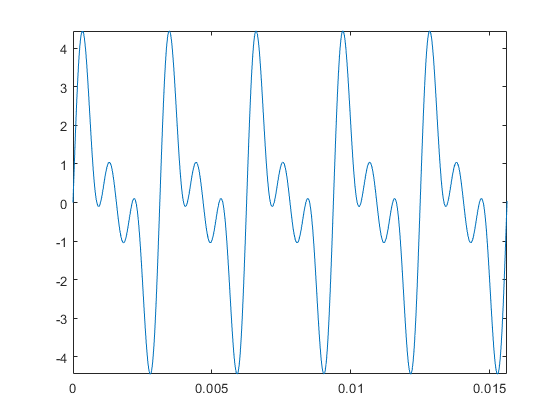

dt = 0.00001;
dur = 1;
t = 0:dt:dur;
switch wave
    case 'sine'
        sig = amp*sin(2*pi*freq*t);
        disp('triangle')
    case 'square'
        sig = amp*square(2*pi*freq*t);
        disp('triangle')
    case 'triangle'
        sig = amp*sawtooth(2*pi*freq*t);
        disp('triangle')
    case 'modulate'
        sig = amp*sin(2*pi*freq*t)+0.9*amp*sin(2*pi*2*freq*t)+0.8*amp*sin(2*pi*3*freq*t);
end
sound(sig,1/dt); 
plot(t,sig); axis([0 5/freq -inf inf]);
pause(dur);

傅里叶变换

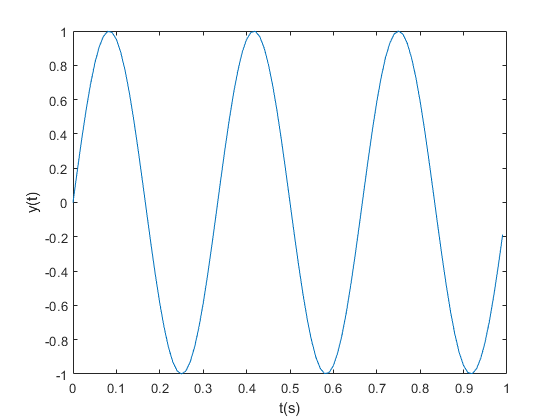

clear;clf;
dt = 0.01; Fs = 1/dt;
t = 0:dt:1-dt;
y = sin(2*pi*3*t);
N = length(y);
f = (-N/2:N/2-1)*Fs/N;
Y = fftshift(fft(y))/N;
plot(t,y); xlabel('t(s)');ylabel('y(t)')

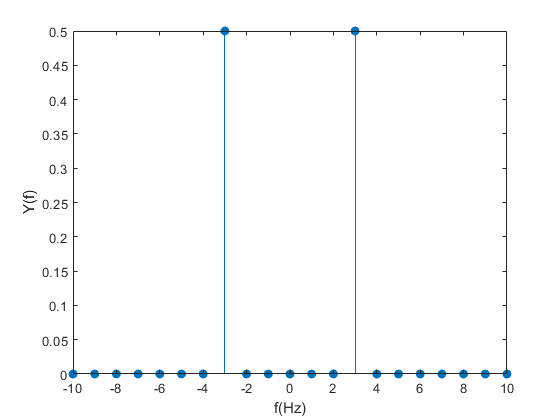

figure;
stem(f,abs(Y),'filled');axis([-10 10 0 inf]);
xlabel('f(Hz)');ylabel('Y(f)')